# **Proyecto Conjunto MATLAB/MATHEMATICA**

## **Sistema láser bombeado ópticamente con dependencia espacial**

Realizado por Isabel Rodríguez y Javier Gil

rect=[0, 0, 520, 410]; %%Tamaño del frame de los videos
%%Vector de la forma: [left bottom width height]

%____________________________VIDEO_DENSIDAD_DE_FOTONES____________________________
bi=1; %%Frame inicial
bf=10; %%Frame final
ndz=(bf-bi) %%Número de frames

ndz = 9

nomFile = 'frame1.dat'

filename = 'densidad1.jpg'

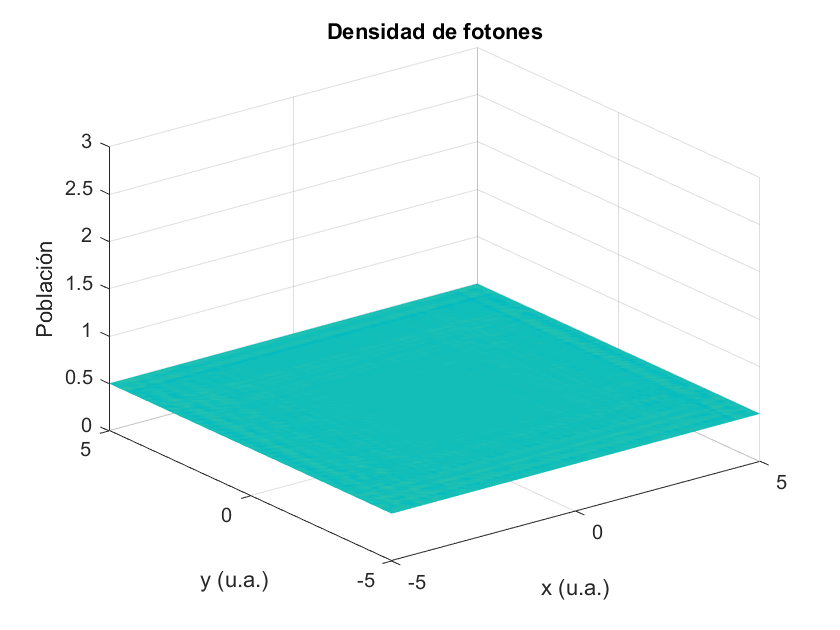

j = 1

nomFile = 'frame2.dat'

filename = 'densidad2.jpg'

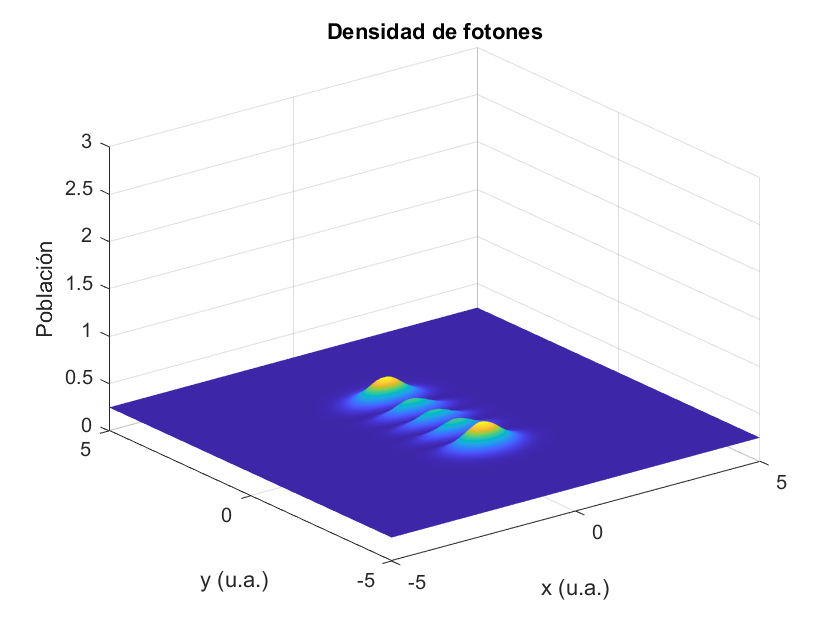

j = 2

nomFile = 'frame3.dat'

filename = 'densidad3.jpg'

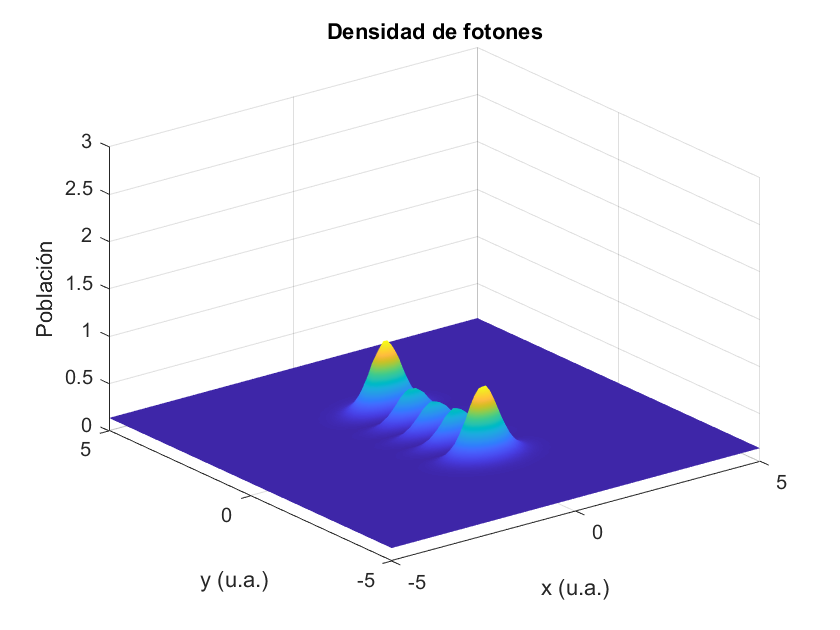

j = 3

nomFile = 'frame4.dat'

filename = 'densidad4.jpg'

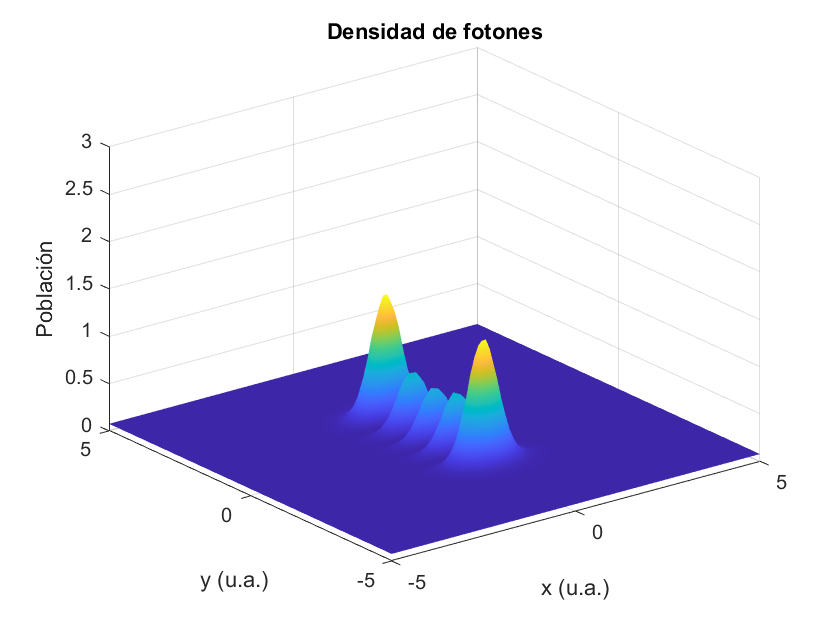

j = 4

nomFile = 'frame5.dat'

filename = 'densidad5.jpg'

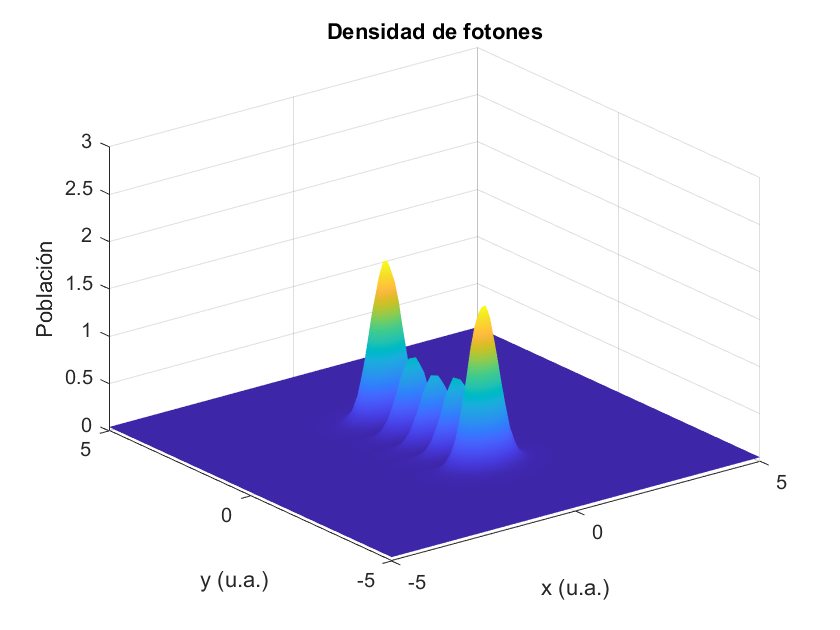

j = 5

nomFile = 'frame6.dat'

filename = 'densidad6.jpg'

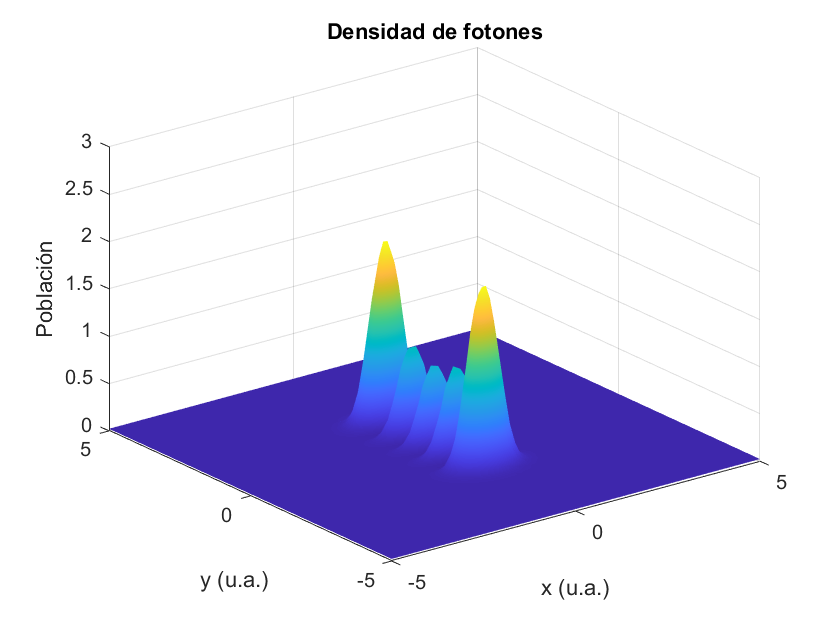

j = 6

nomFile = 'frame7.dat'

filename = 'densidad7.jpg'

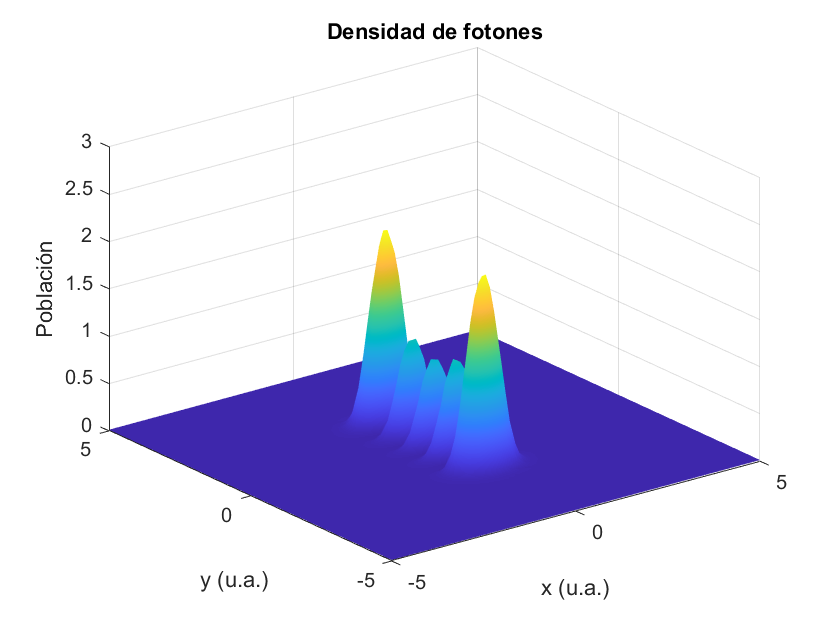

j = 7

nomFile = 'frame8.dat'

filename = 'densidad8.jpg'

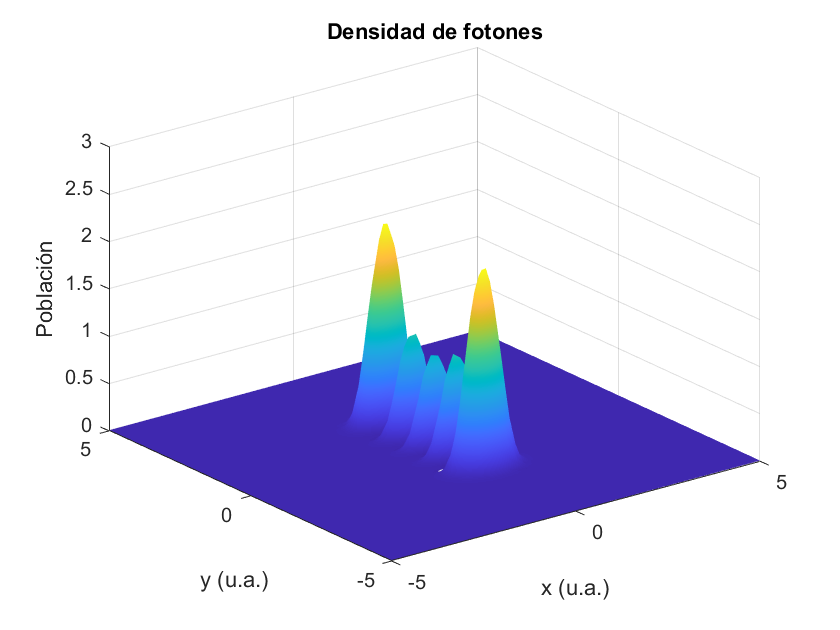

j = 8

nomFile = 'frame9.dat'

filename = 'densidad9.jpg'

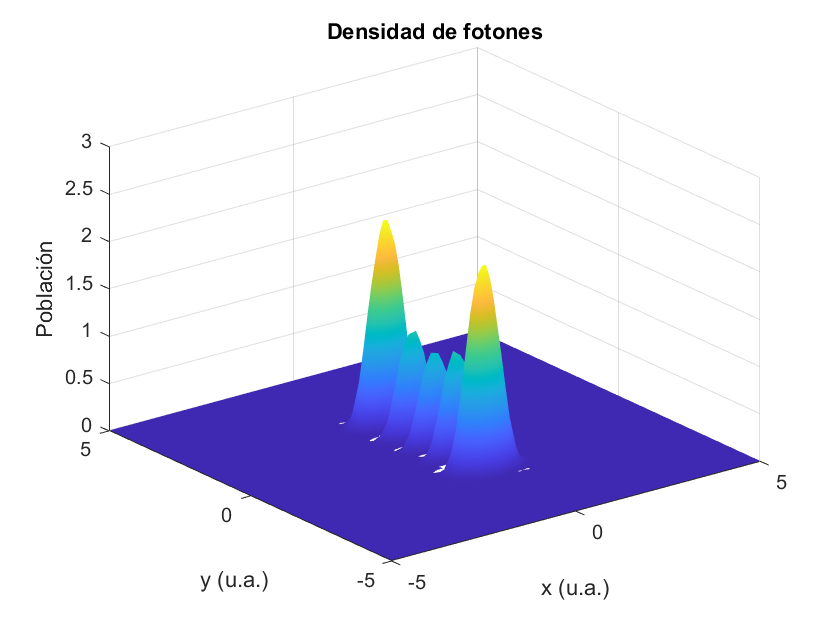

j = 9

nomFile = 'frame10.dat'

filename = 'densidad10.jpg'

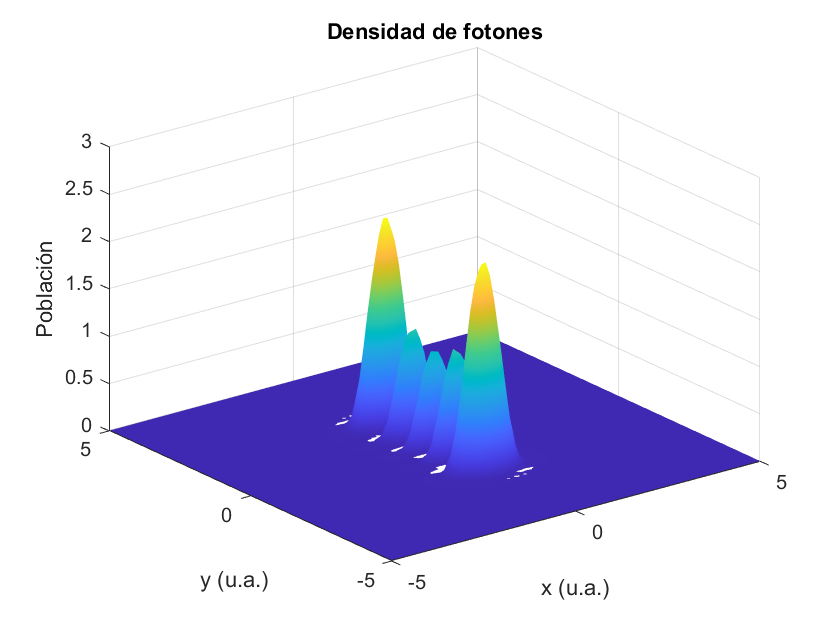

j = 10

Densidad(ndz)=struct('cdata',[],'colormap',[]); %%Array que guarda cada captura
for j=bi:bf %%Bucle de frames
    %%FICHEROS QUE IMPORTAMOS DE MATHEMATICA
    %%Importamos el frame con el mismo num que el indice j
    nomFile=sprintf('frame%d.dat',j)
    %%Especificamos la separación entre una columna y otra
    Esp=importdata(nomFile,'	'); 
    x=Esp(:,1); %%primera columna son las x
    y=Esp(:,2); %%segunda comlumna las y
    z=Esp(:,3); %%densidad de fotones
    
    %%Hacemos un mallado para representar la densidad de fotones en 3D
    xlin=linspace(min(x),max(x),90); %%90 medidas desde el valor mínimo al máximo
    ylin=linspace(min(y),max(y),90);
    [X,Y]=meshgrid(xlin,ylin);
    Z=griddata(x,y,z,X,Y,'cubic'); 

    

    figure %%La representación de cada frame se representa como una figura
    surf(X,Y,Z)
    shading interp %%Diseño para que quede bonito
    title('Densidad de fotones', 'FontSize', 16, 'FontName', 'Helvetica');
    xlabel(' x (u.a.)', 'FontSize', 12, 'FontName', 'Helvetica');
    ylabel(' y (u.a.)', 'FontSize', 12, 'FontName', 'Helvetica');
    zlabel('Población', 'FontSize', 12, 'FontName', 'Helvetica');
    set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
    zlim([0,3]) 
        
    %%La representación se guarda como una imagen jpg
    filename=sprintf('densidad%d.jpg',j)
    Densidad(j) = getframe(gcf,rect);
    %%gcf: Captura el interior de la figure window excluyendo la barra de
    %%menu y de herramientas
    
    %%rect: Se captura los pixeles especificados en rect
            
    j
end



%%Creación del video
v = VideoWriter('Densidaddefotones.avi','Motion JPEG AVI'); 
%%Creamos el archivo de video en el formato y nombre especificado
v.FrameRate=5;
v.Quality=100;
open(v); %%Abrimos el video
writeVideo(v,Densidad); 
%%Escribe la matriz de datos Densidad en el archivo de video v
close(v); %%Cerramos el video

%____________________________VIDEO_POBLACIÓN_NIVEL_1____________________________
%%Análogo al caso anterior
ci=1

ci = 1

cf=16

cf = 16

ndz1=cf-ci

ndz1 = 15

nomFile = 'nivel11.dat'

z =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


filename = 'nivel11.jpg'

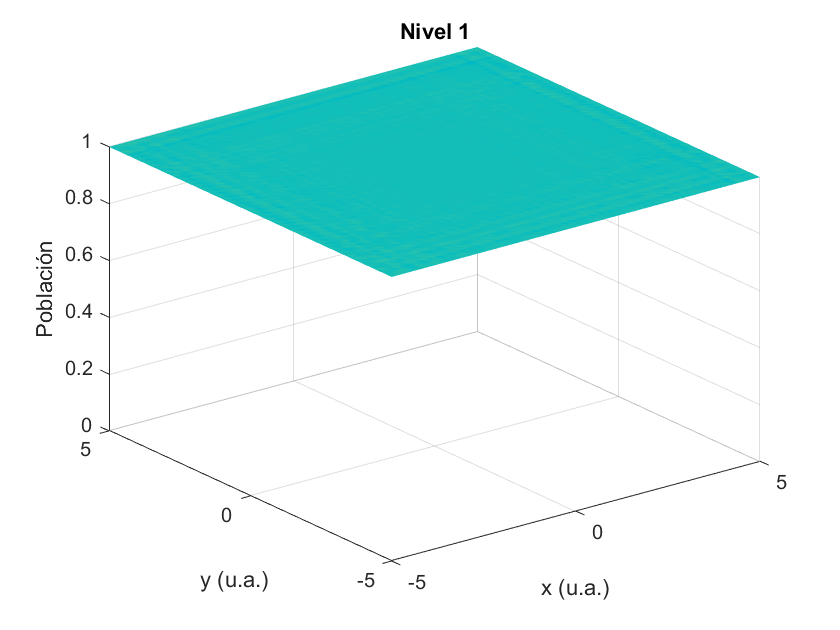

j = 1

nomFile = 'nivel12.dat'

z =     0.6302
    0.6302
    0.6302
    0.6302
    0.6302
    0.6302
    0.6302
    0.6302
    0.6302
    0.6302


filename = 'nivel12.jpg'

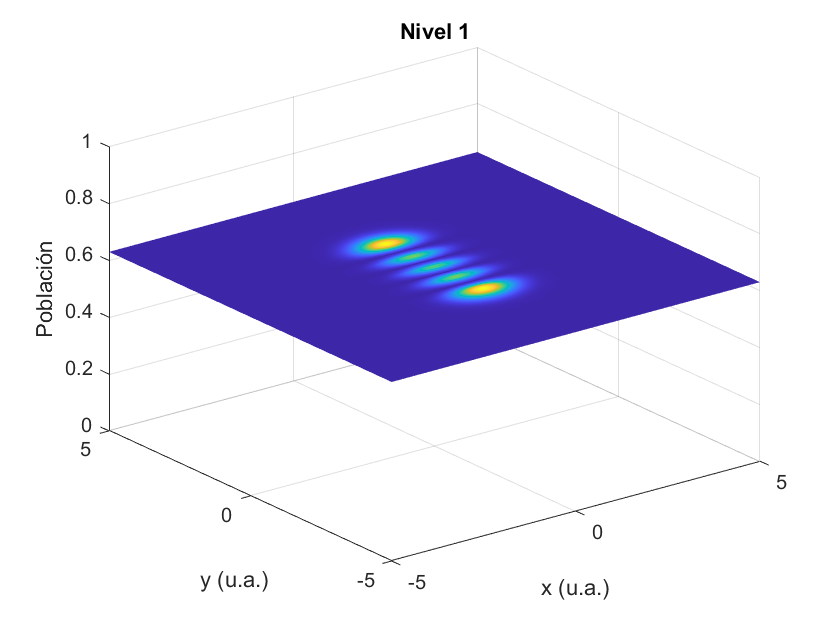

j = 2

nomFile = 'nivel13.dat'

z =     0.3990
    0.3990
    0.3990
    0.3990
    0.3990
    0.3990
    0.3990
    0.3990
    0.3990
    0.3990


filename = 'nivel13.jpg'

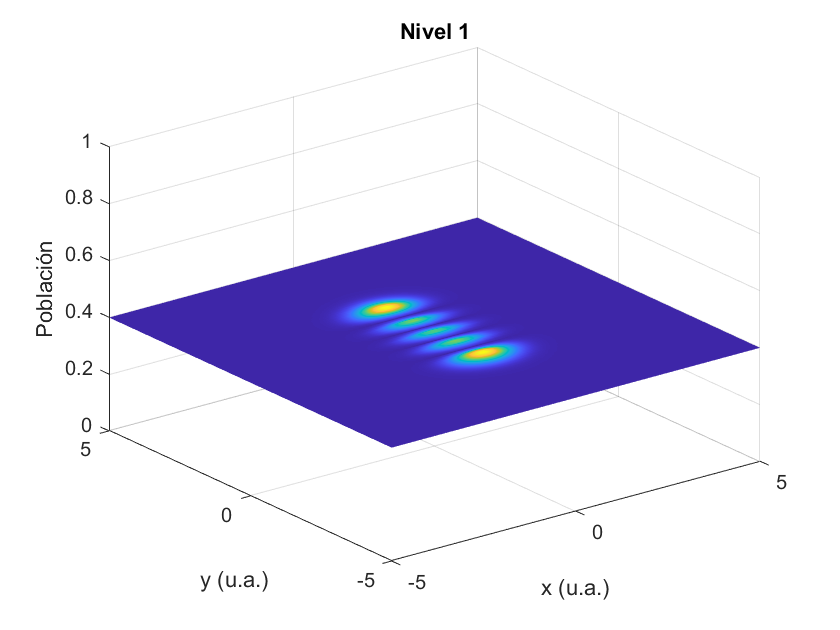

j = 3

nomFile = 'nivel14.dat'

z =     0.2540
    0.2540
    0.2540
    0.2540
    0.2540
    0.2540
    0.2540
    0.2540
    0.2540
    0.2540


filename = 'nivel14.jpg'

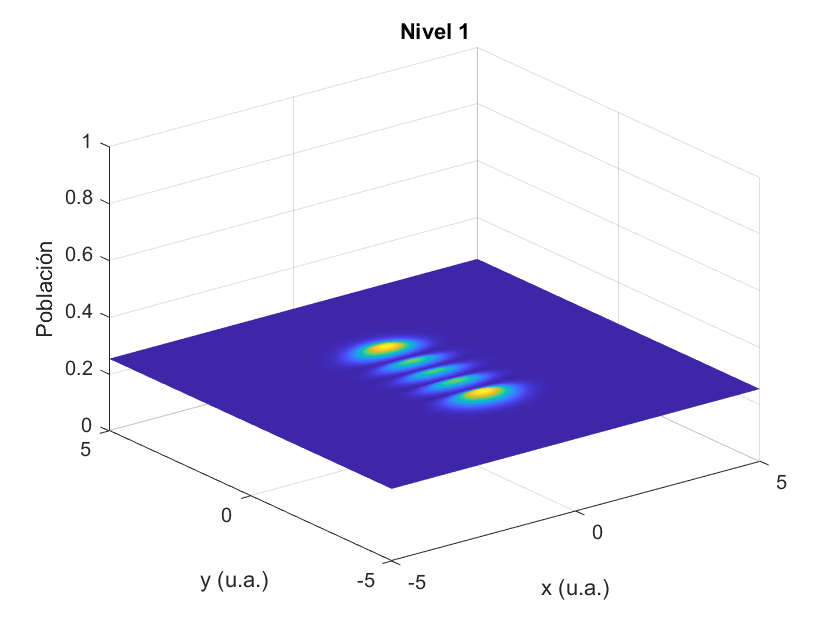

j = 4

nomFile = 'nivel15.dat'

z =     0.1627
    0.1627
    0.1627
    0.1627
    0.1627
    0.1627
    0.1627
    0.1627
    0.1627
    0.1627


filename = 'nivel15.jpg'

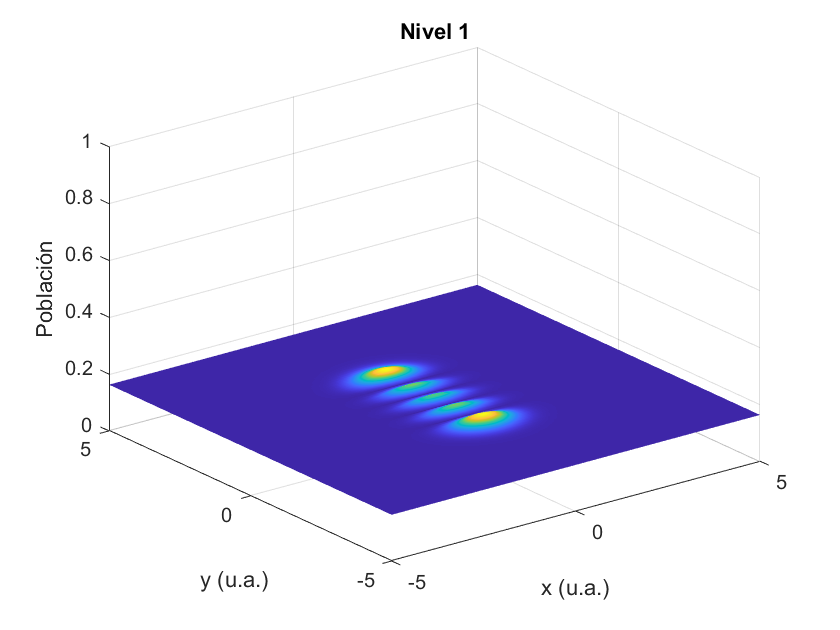

j = 5

nomFile = 'nivel16.dat'

z =     0.1051
    0.1051
    0.1051
    0.1051
    0.1051
    0.1051
    0.1051
    0.1051
    0.1051
    0.1051


filename = 'nivel16.jpg'

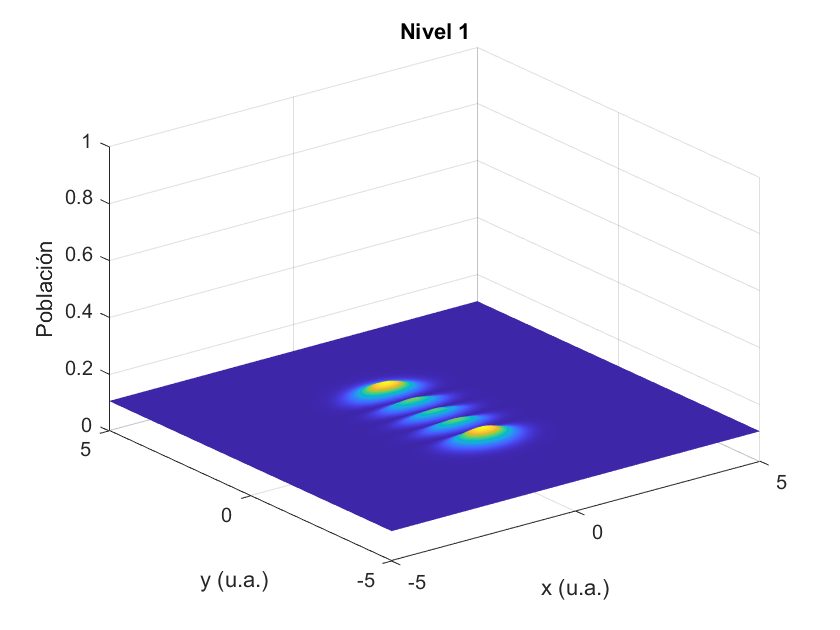

j = 6

nomFile = 'nivel17.dat'

z =     0.0687
    0.0687
    0.0687
    0.0687
    0.0687
    0.0687
    0.0687
    0.0687
    0.0687
    0.0687


filename = 'nivel17.jpg'

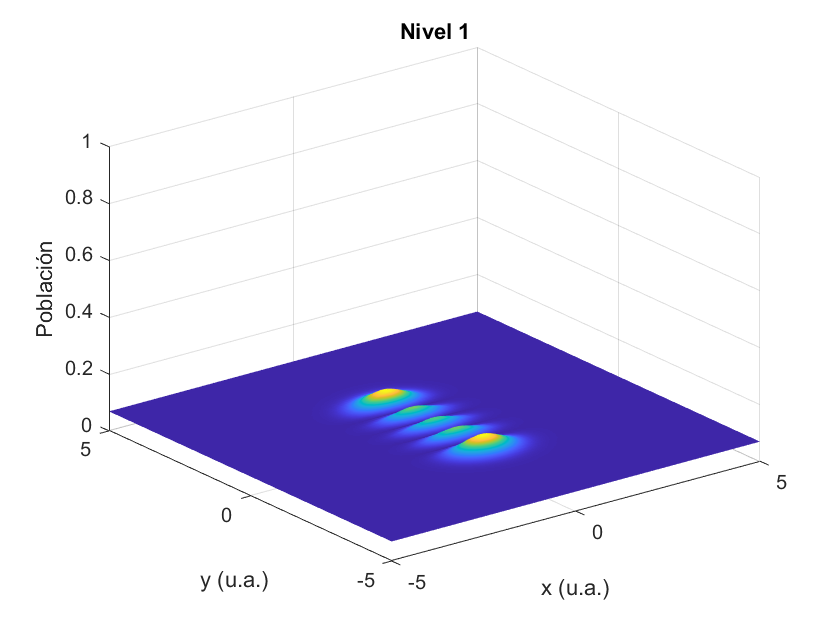

j = 7

nomFile = 'nivel18.dat'

z =     0.0456
    0.0456
    0.0456
    0.0456
    0.0456
    0.0456
    0.0456
    0.0456
    0.0456
    0.0456


filename = 'nivel18.jpg'

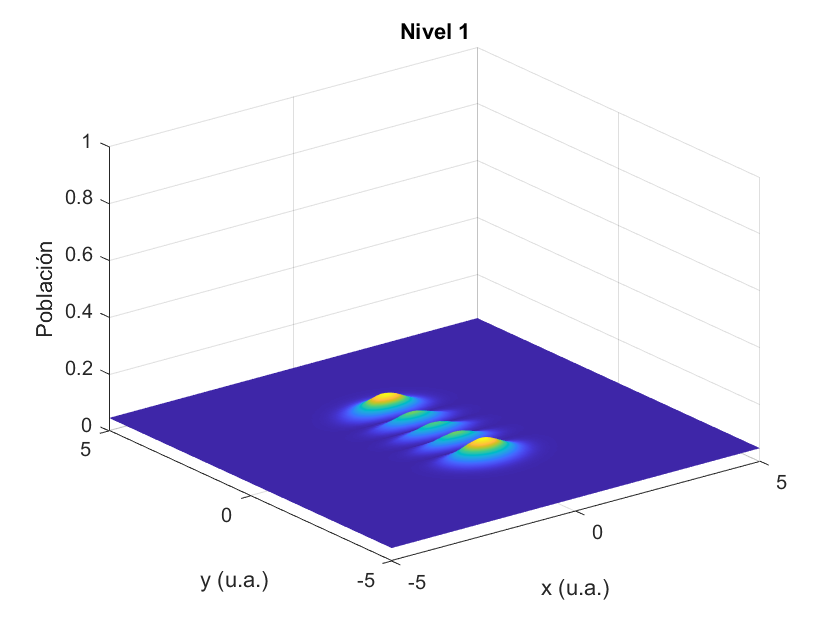

j = 8

nomFile = 'nivel19.dat'

z =     0.0309
    0.0309
    0.0309
    0.0309
    0.0309
    0.0309
    0.0309
    0.0309
    0.0309
    0.0309


filename = 'nivel19.jpg'

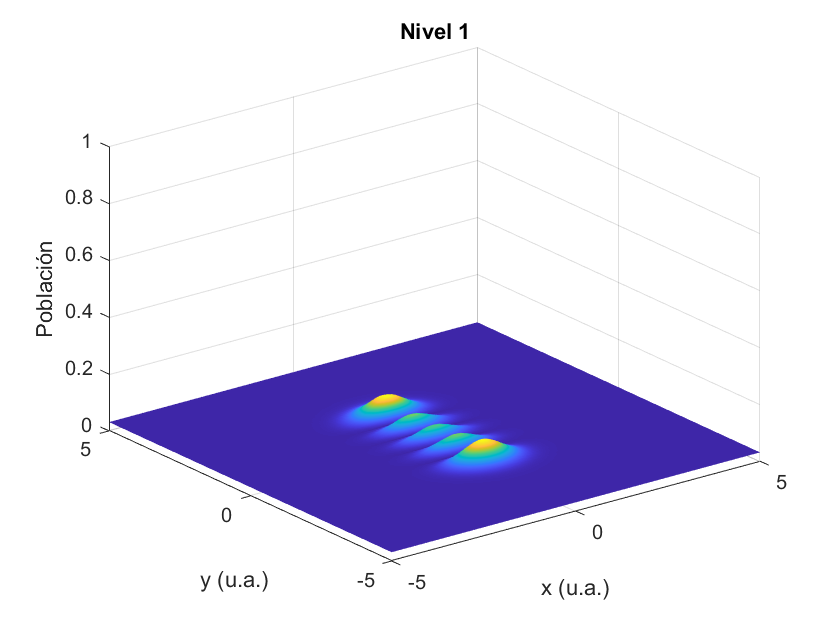

j = 9

nomFile = 'nivel110.dat'

z =     0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214
    0.0214


filename = 'nivel110.jpg'

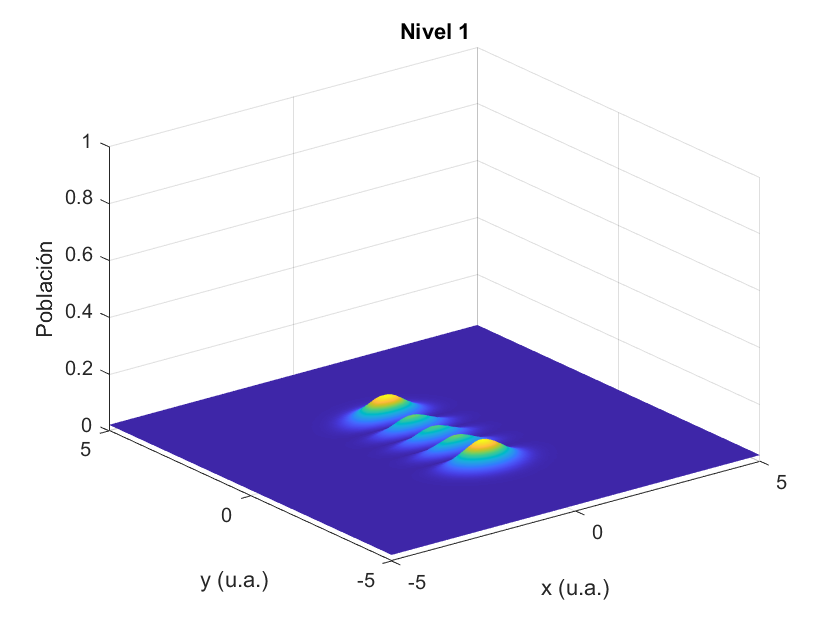

j = 10

nomFile = 'nivel111.dat'

z =     0.0154
    0.0154
    0.0154
    0.0154
    0.0154
    0.0154
    0.0154
    0.0154
    0.0154
    0.0154


filename = 'nivel111.jpg'

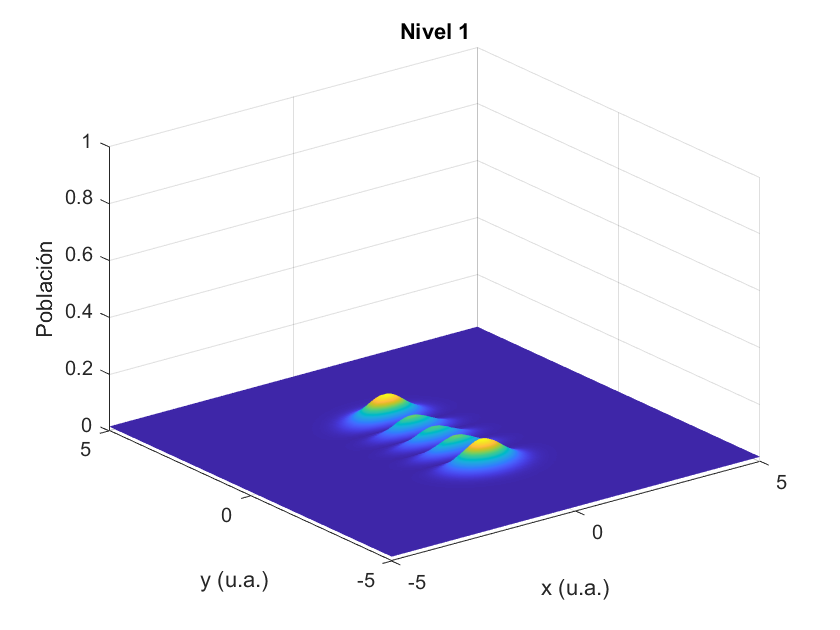

j = 11

nomFile = 'nivel112.dat'

z =     0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0114
    0.0114


filename = 'nivel112.jpg'

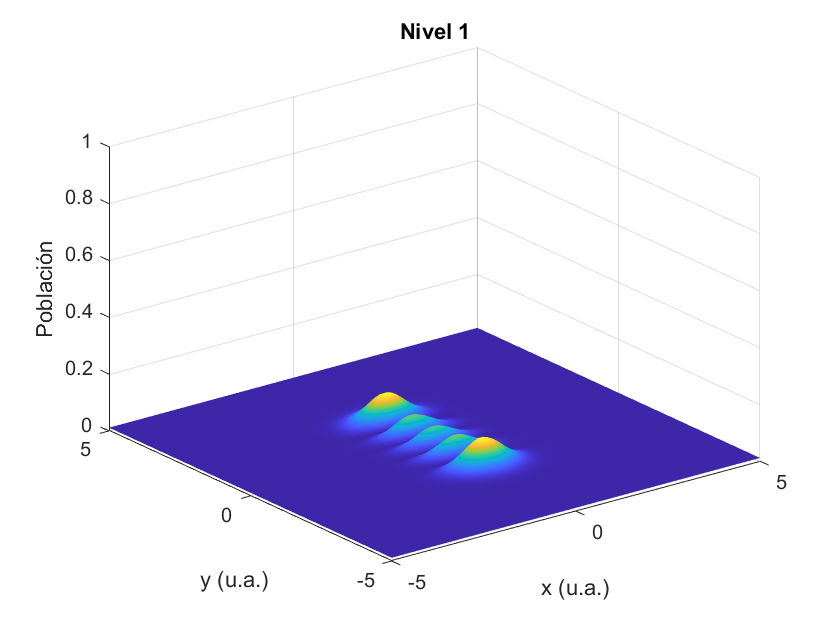

j = 12

nomFile = 'nivel113.dat'

z =     0.0088
    0.0088
    0.0088
    0.0088
    0.0088
    0.0088
    0.0088
    0.0088
    0.0088
    0.0088


filename = 'nivel113.jpg'

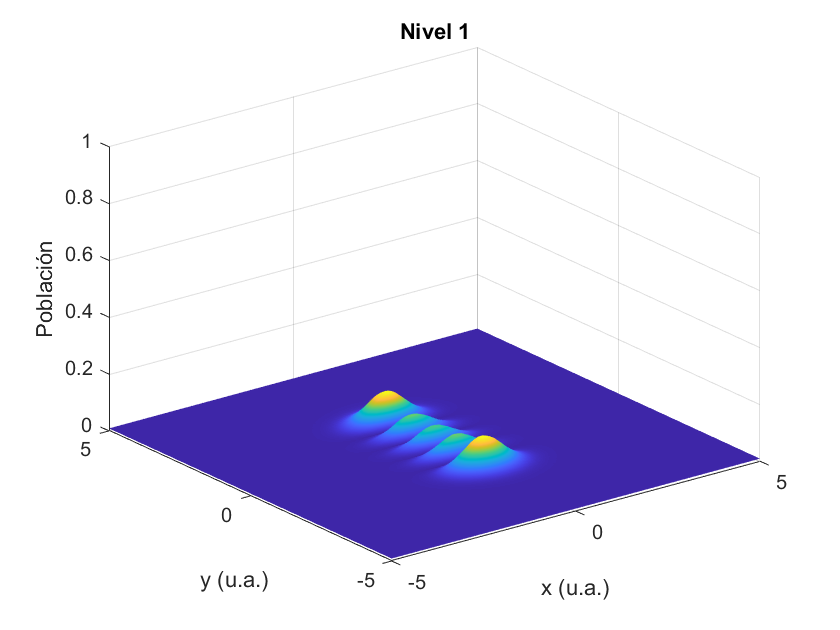

j = 13

nomFile = 'nivel114.dat'

z =     0.0070
    0.0070
    0.0070
    0.0070
    0.0070
    0.0070
    0.0070
    0.0070
    0.0070
    0.0070


filename = 'nivel114.jpg'

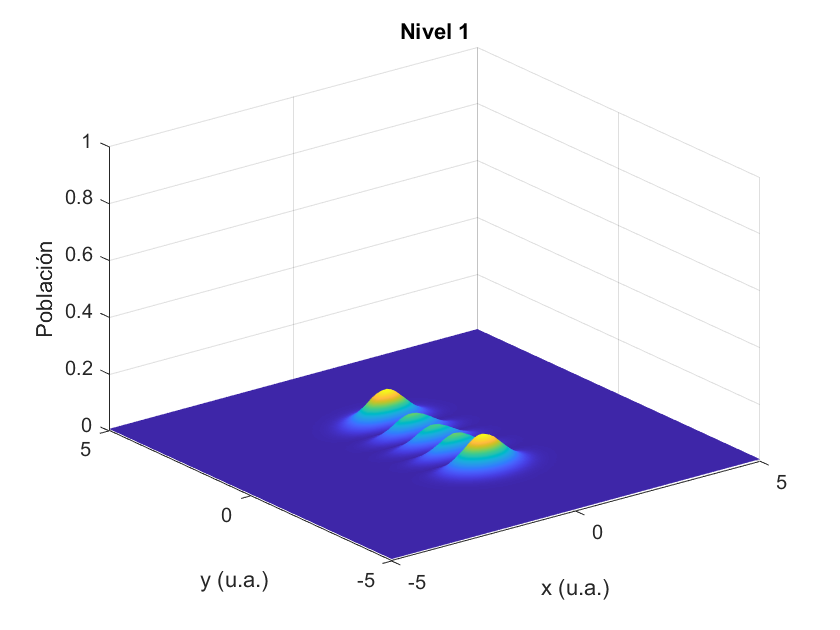

j = 14

nomFile = 'nivel115.dat'

z =     0.0058
    0.0058
    0.0058
    0.0058
    0.0058
    0.0058
    0.0058
    0.0058
    0.0058
    0.0058


filename = 'nivel115.jpg'

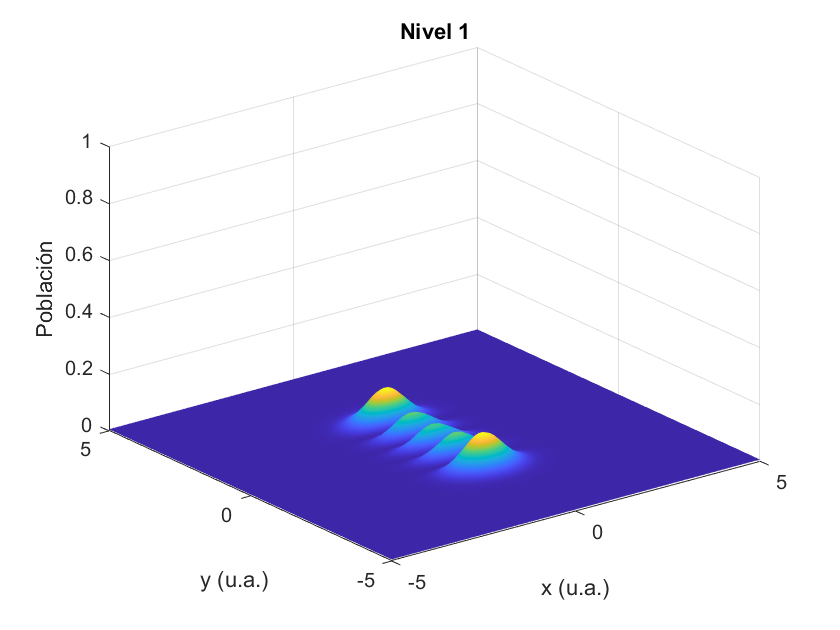

j = 15

nomFile = 'nivel116.dat'

z =     0.0050
    0.0050
    0.0050
    0.0050
    0.0050
    0.0050
    0.0050
    0.0050
    0.0050
    0.0050


filename = 'nivel116.jpg'

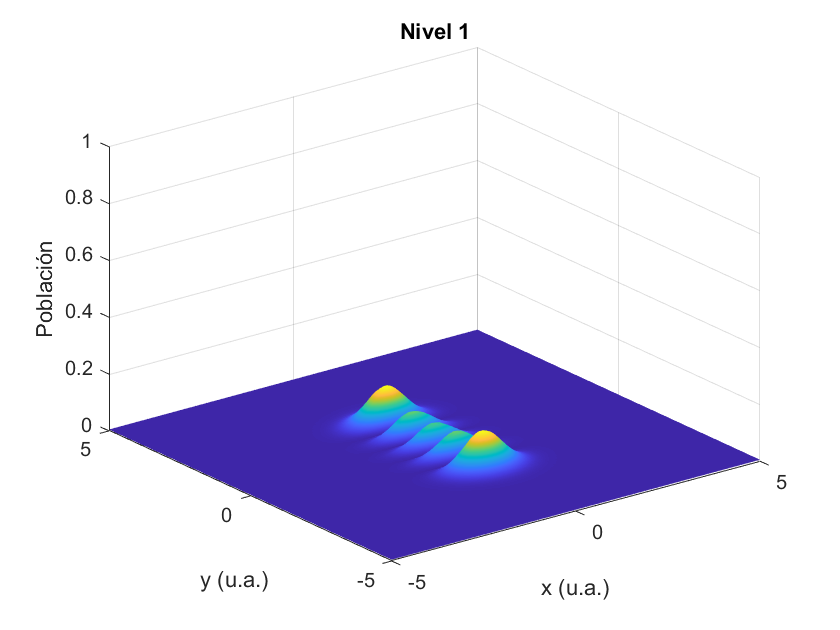

j = 16

nivel1(ndz1)=struct('cdata',[],'colormap',[]);
for j=ci:cf
    nomFile=sprintf('nivel1%d.dat',j)
    Esp=importdata(nomFile,'	');
    x=Esp(:,1);
    y=Esp(:,2);
    z=Esp(:,3)

    xlin=linspace(min(x),max(x),90);
    ylin=linspace(min(y),max(y),90);
    [X,Y]=meshgrid(xlin,ylin);
    Z=griddata(x,y,z,X,Y,'cubic'); 

    

    figure
    surf(X,Y,Z)
    shading interp
    title('Nivel 1', 'FontSize', 16, 'FontName', 'Helvetica');
    xlabel(' x (u.a.)', 'FontSize', 12, 'FontName', 'Helvetica');
    ylabel(' y (u.a.)', 'FontSize', 12, 'FontName', 'Helvetica');
    zlabel('Población', 'FontSize', 12, 'FontName', 'Helvetica');
    set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
    zlim([0,1]) 
        
        
    filename=sprintf('nivel1%d.jpg',j)
    nivel1(j) = getframe(gcf,rect);
            
    j
end

nomFile = 'nivel21.dat'

z =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


filename = 'nivel21.jpg'

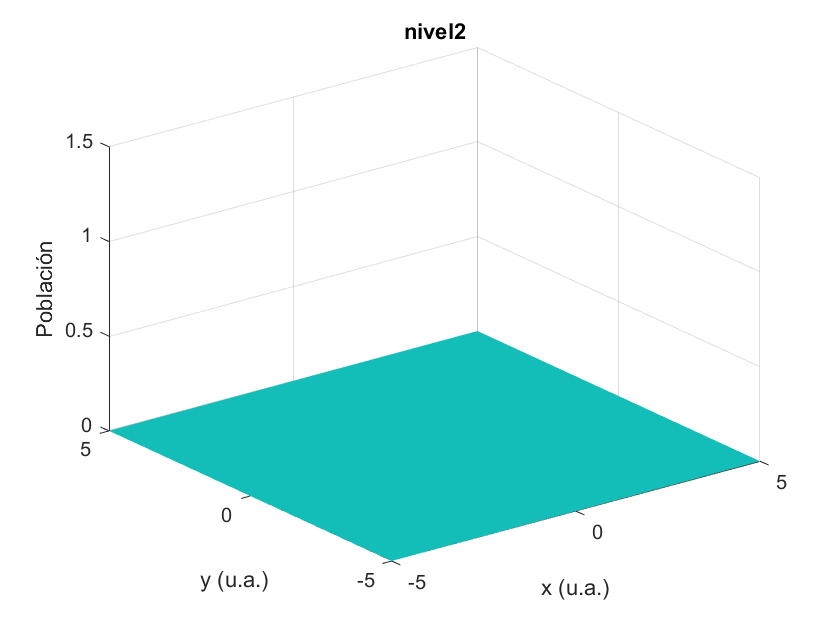

j = 1

nomFile = 'nivel22.dat'

z =     0.0336
    0.0336
    0.0336
    0.0336
    0.0336
    0.0336
    0.0336
    0.0336
    0.0336
    0.0336


filename = 'nivel22.jpg'

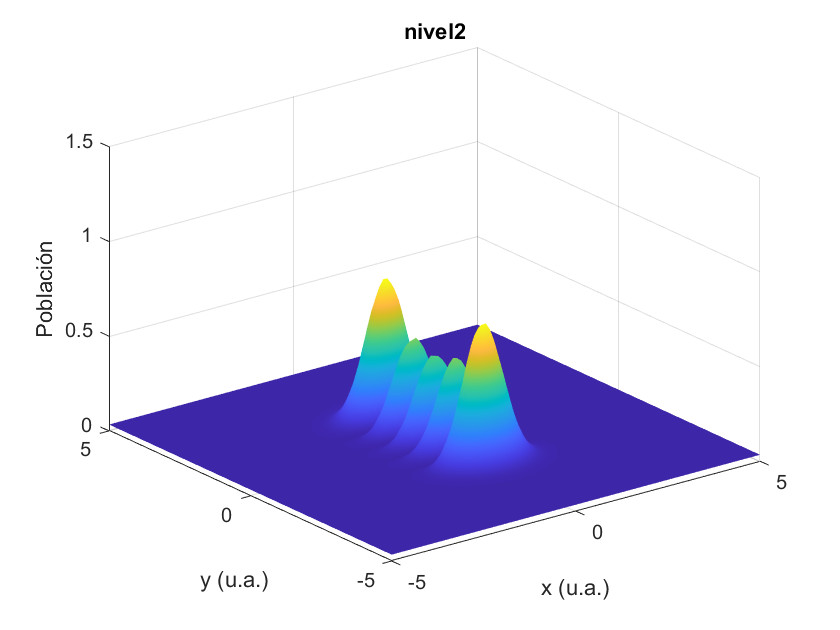

j = 2

nomFile = 'nivel23.dat'

z =     0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191
    0.0191


filename = 'nivel23.jpg'

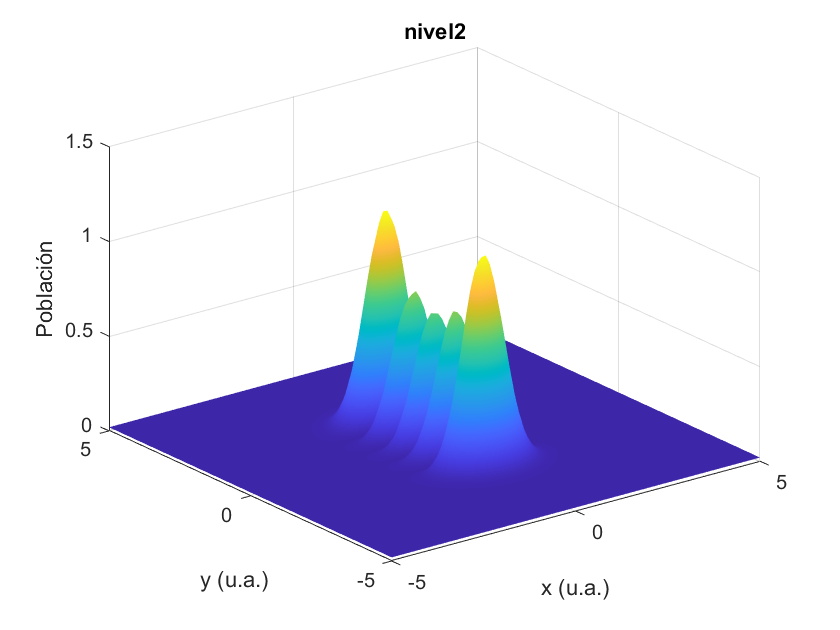

j = 3

nomFile = 'nivel24.dat'

z =     0.0111
    0.0111
    0.0111
    0.0111
    0.0111
    0.0111
    0.0111
    0.0111
    0.0111
    0.0111


filename = 'nivel24.jpg'

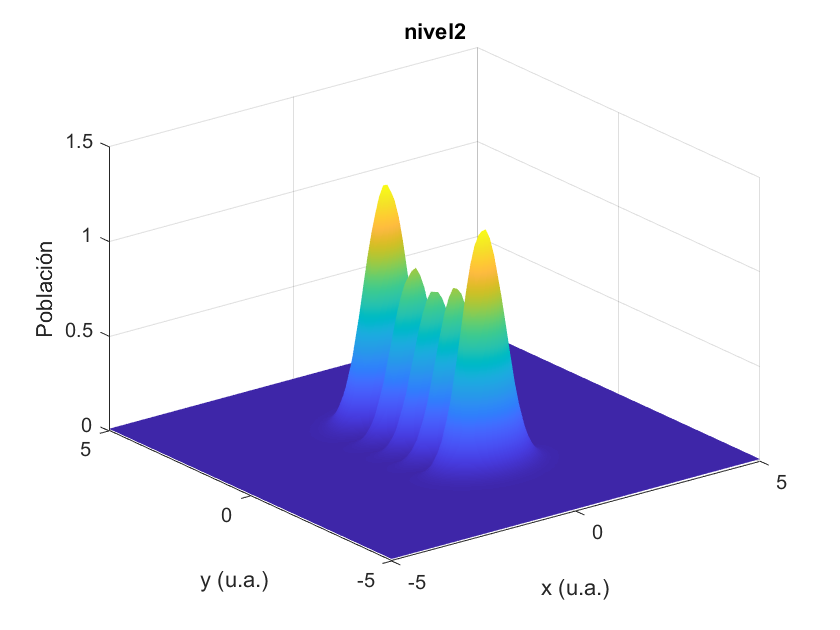

j = 4

nomFile = 'nivel25.dat'

z =     0.0067
    0.0067
    0.0067
    0.0067
    0.0067
    0.0067
    0.0067
    0.0067
    0.0067
    0.0067


filename = 'nivel25.jpg'

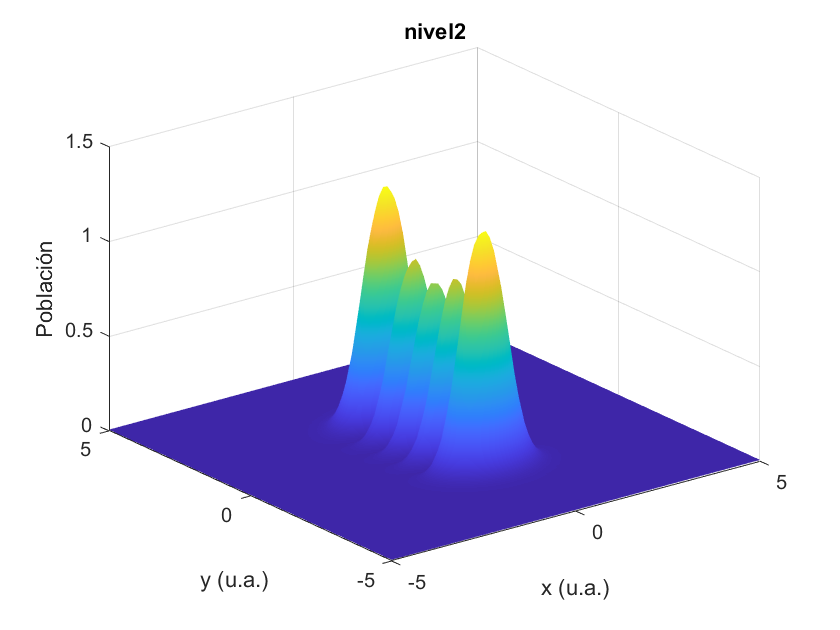

j = 5

nomFile = 'nivel26.dat'

z =     0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041
    0.0041


filename = 'nivel26.jpg'

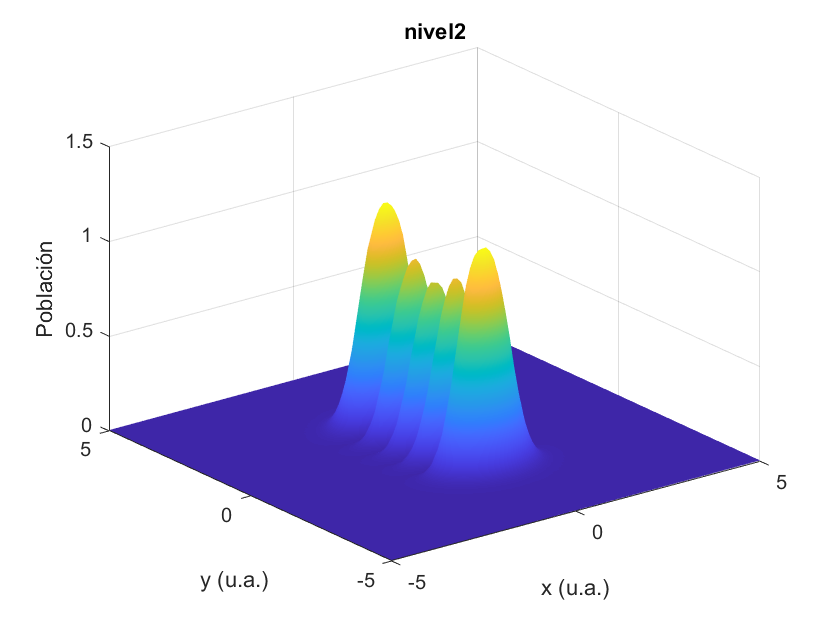

j = 6

nomFile = 'nivel27.dat'

z =     0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025
    0.0025


filename = 'nivel27.jpg'

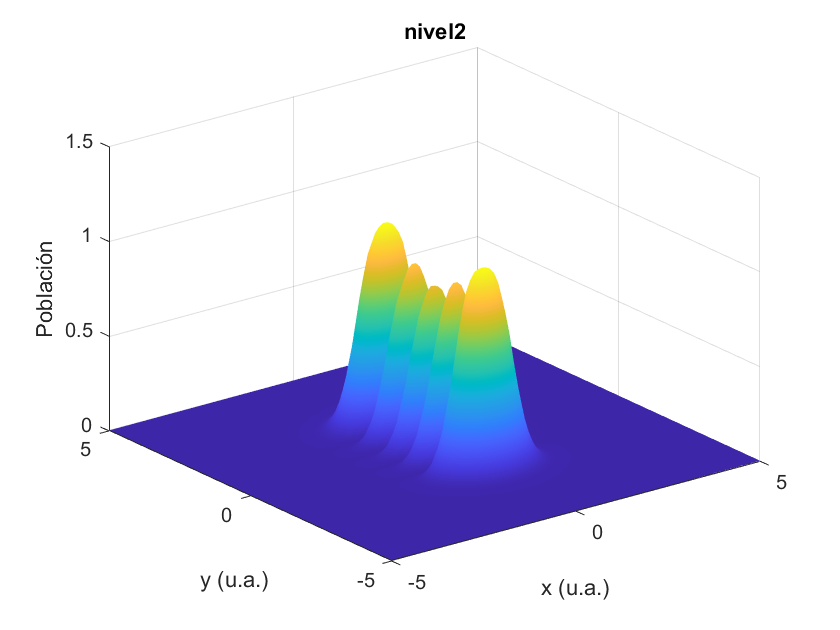

j = 7

nomFile = 'nivel28.dat'

z =     0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016
    0.0016


filename = 'nivel28.jpg'

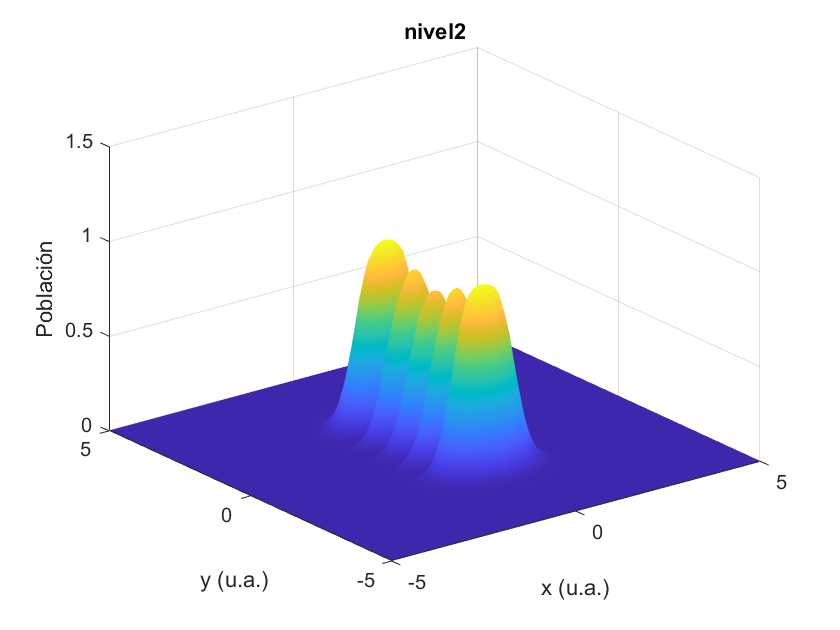

j = 8

nomFile = 'nivel29.dat'

z =     0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010
    0.0010


filename = 'nivel29.jpg'

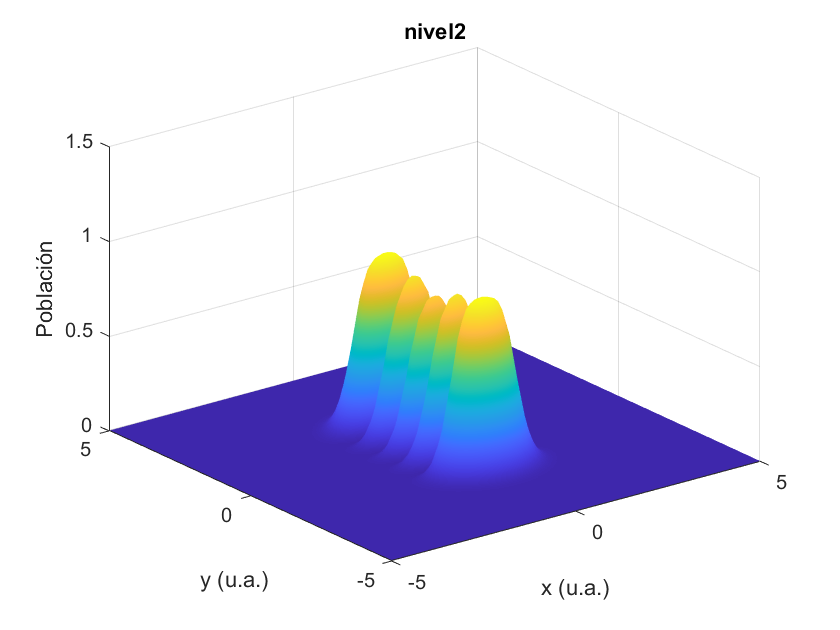

j = 9

nomFile = 'nivel210.dat'

z =     0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006
    0.0006


filename = 'nivel210.jpg'

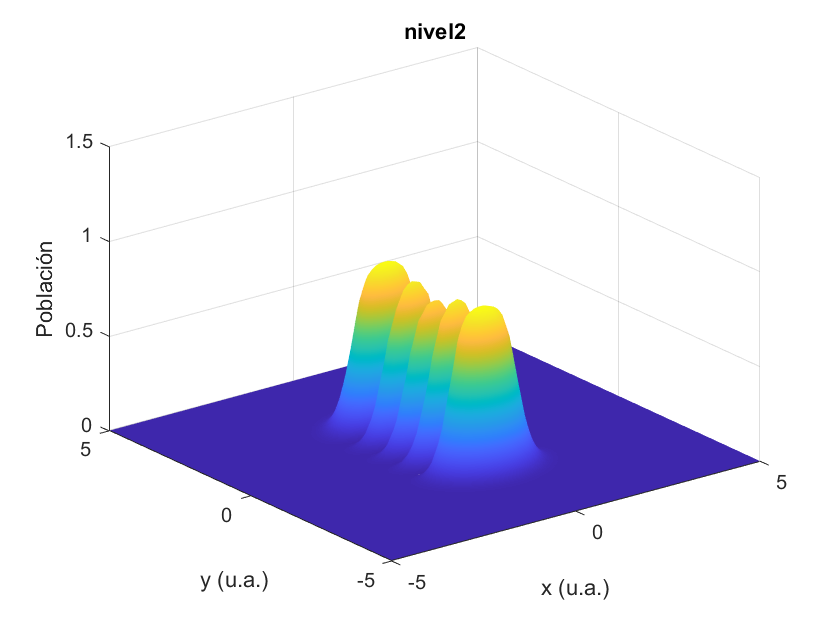

j = 10

nomFile = 'nivel211.dat'

z =     0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004
    0.0004


filename = 'nivel211.jpg'

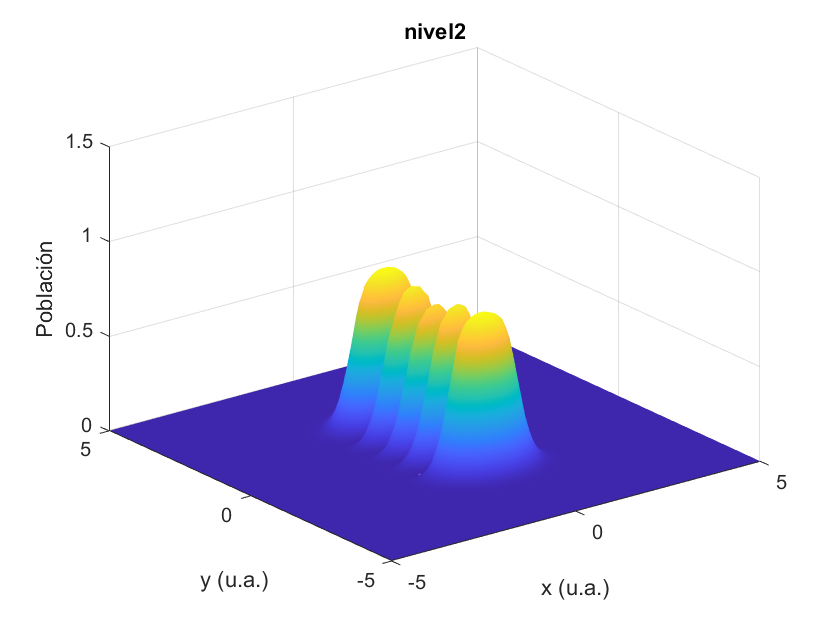

j = 11

nomFile = 'nivel212.dat'

z =     0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003
    0.0003


filename = 'nivel212.jpg'

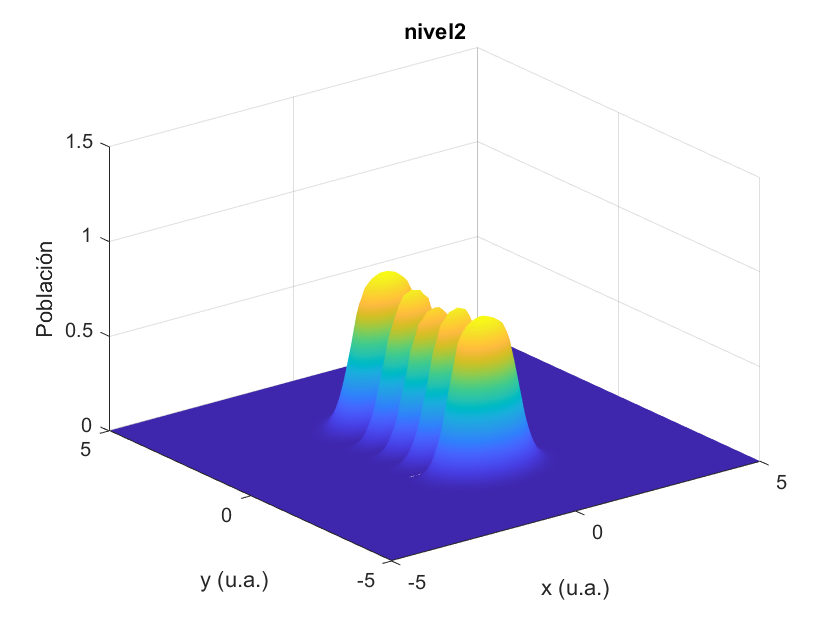

j = 12

nomFile = 'nivel213.dat'

z =     0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002
    0.0002


filename = 'nivel213.jpg'

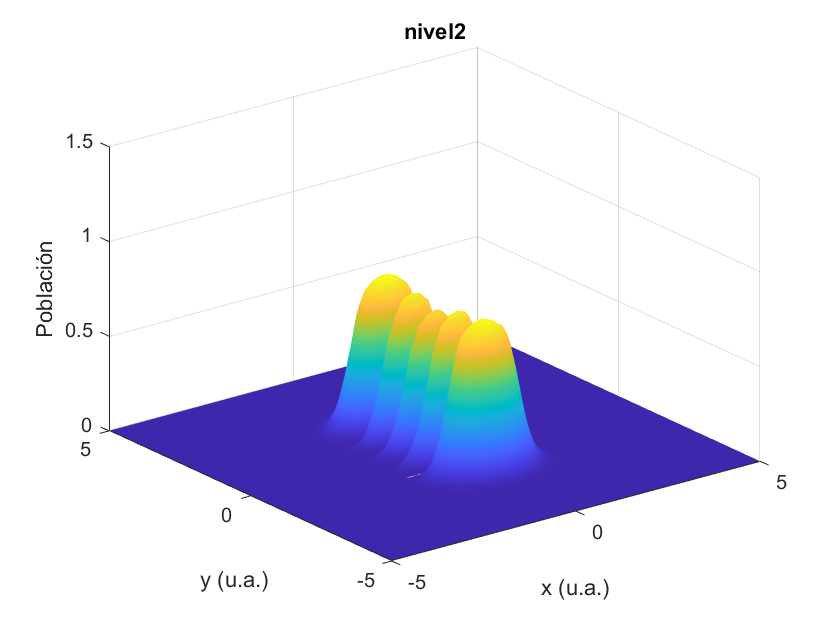

j = 13

nomFile = 'nivel214.dat'

z =     0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


filename = 'nivel214.jpg'

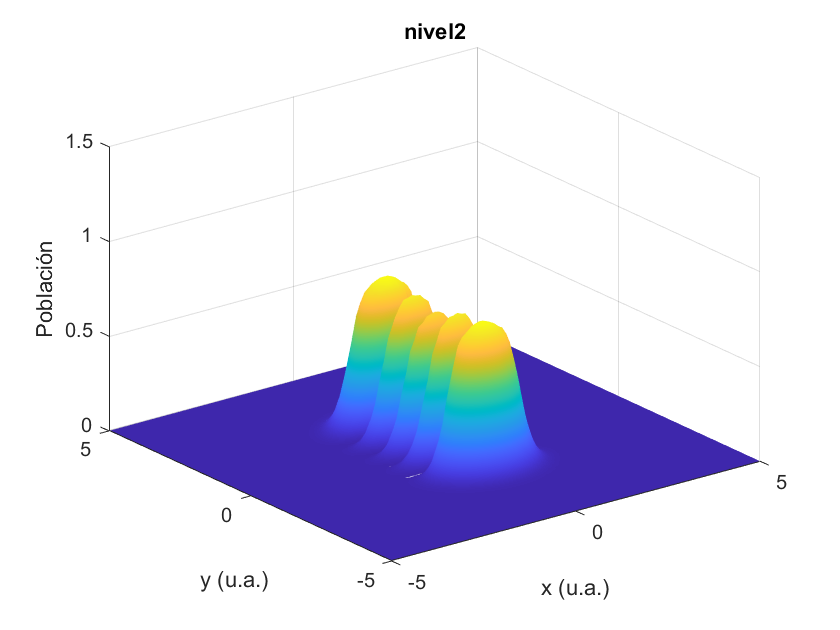

j = 14

nomFile = 'nivel215.dat'

z =     0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001
    0.0001


filename = 'nivel215.jpg'

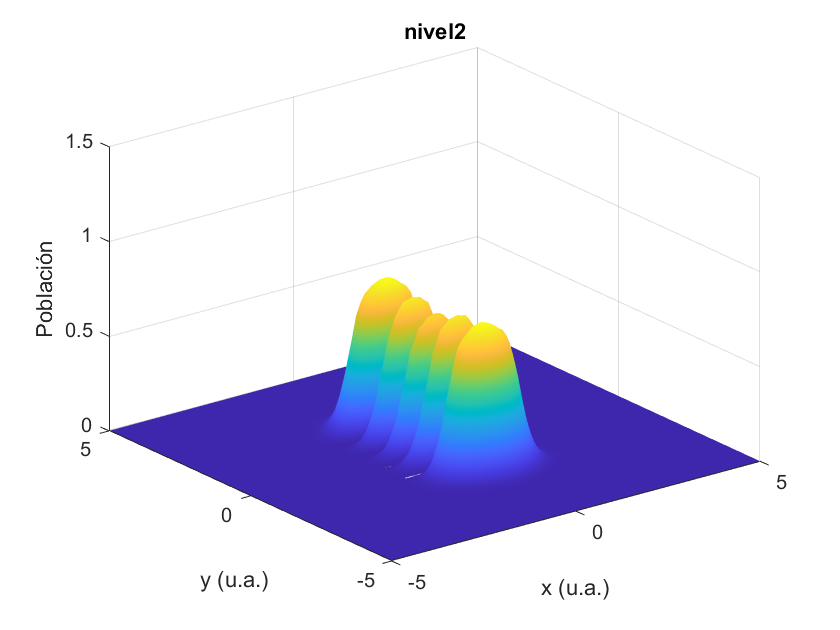

j = 15

nomFile = 'nivel216.dat'

z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


filename = 'nivel216.jpg'

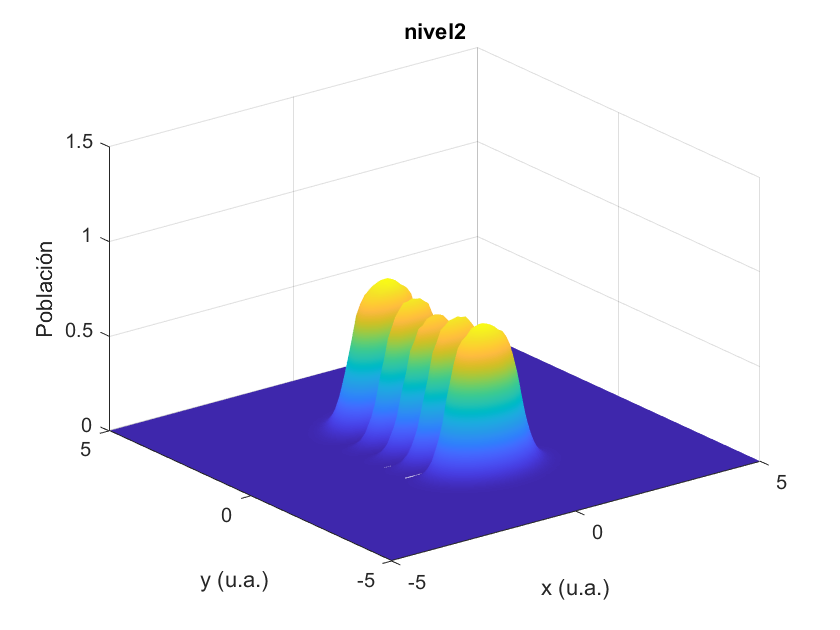

j = 16

nomFile = 'nivel217.dat'

z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


filename = 'nivel217.jpg'

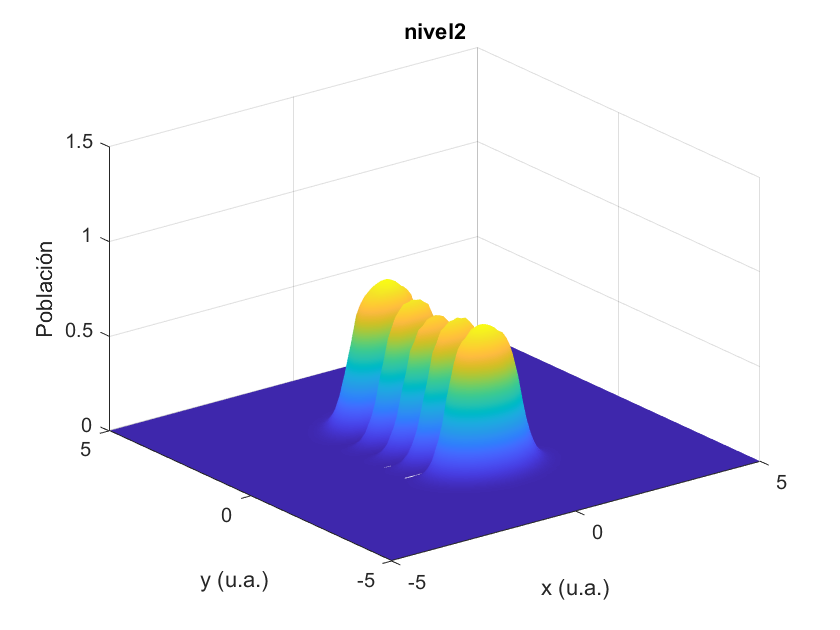

j = 17

nomFile = 'nivel218.dat'

z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


filename = 'nivel218.jpg'

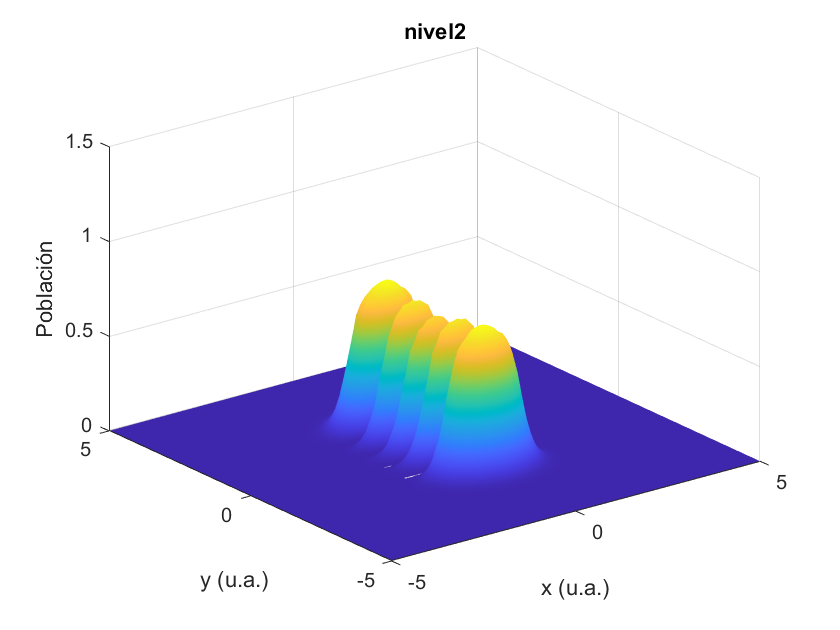

j = 18

nomFile = 'nivel219.dat'

z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


filename = 'nivel219.jpg'

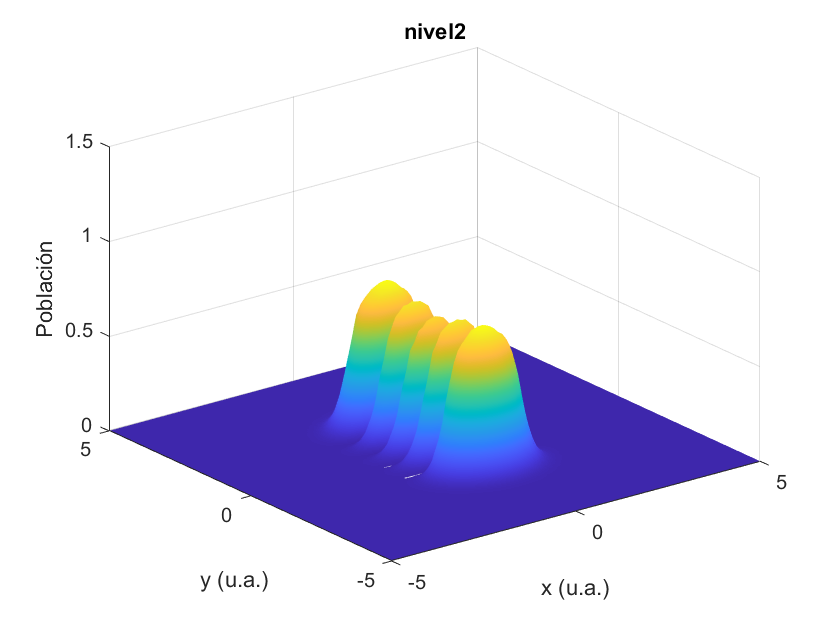

j = 19

nomFile = 'nivel220.dat'

z =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


filename = 'nivel220.jpg'

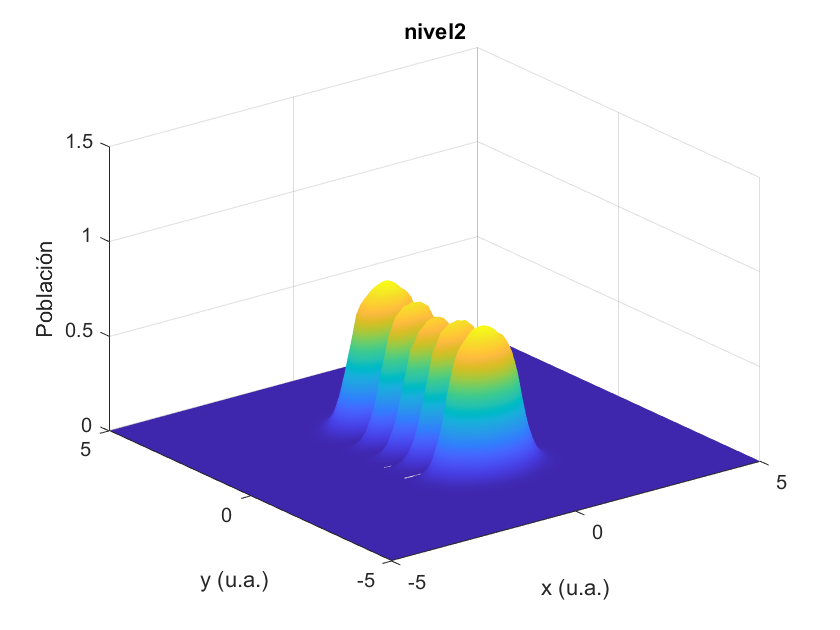

j = 20


u = VideoWriter('nivel1.avi','Motion JPEG AVI');
u.FrameRate=5;
u.Quality=100;
open(u);
writeVideo(u,nivel1);
close(u);

%____________________________VIDEO_POBLACIÓN_NIVEL_2____________________________
%%Análogo al caso anterior
di=1;
df=20;
ndz2=df-di;
nivel2(ndz2)=struct('cdata',[],'colormap',[]);
for j=di:df
    nomFile=sprintf('nivel2%d.dat',j)
    Esp=importdata(nomFile,'	');
    x=Esp(:,1);
    y=Esp(:,2);
    z=Esp(:,3)

    xlin=linspace(min(x),max(x),90);
    ylin=linspace(min(y),max(y),90);
    [X,Y]=meshgrid(xlin,ylin);
    Z=griddata(x,y,z,X,Y,'cubic'); 

    

    figure
    surf(X,Y,Z)
    shading interp
    title('nivel2', 'FontSize', 16, 'FontName', 'Helvetica');
    xlabel(' x (u.a.)', 'FontSize', 12, 'FontName', 'Helvetica');
    ylabel(' y (u.a.)', 'FontSize', 12, 'FontName', 'Helvetica');
    zlabel('Población', 'FontSize', 12, 'FontName', 'Helvetica');
    set(gca, 'FontSize', 10, 'FontName', 'Helvetica');
    zlim([0,1.5]) 
        
        
    filename=sprintf('nivel2%d.jpg',j)
    nivel2(j) = getframe(gcf,rect);
            
    j
end


w = VideoWriter('nivel2.avi','Motion JPEG AVI');
w.FrameRate=5;
w.Quality=100;
open(w);
writeVideo(w,nivel2);
close(w);

